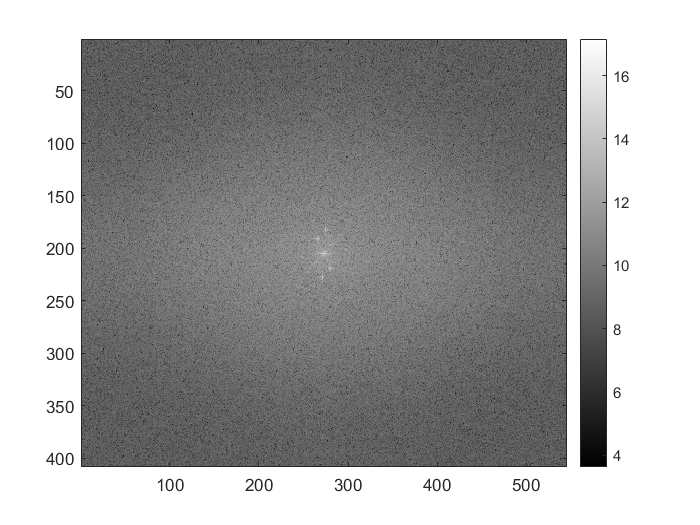


%Main script to read the image in and filter out the periodic signal from
%the image and then correct the non-uniform illumination 
clear; close all;

% fileName = input("Enter the name of the image with extention ex. Image.tif -> ", 's');
imOrig = histeq(imread("Proj4.tif"));

[nx, ny] = size(imOrig);

FT = log(1 + abs(fftshift(fft2(double(imOrig)))));

%FT2 = fft2(double(imOrig));
FT2 =  (1 + abs(fftshift(fft2(double(imOrig)))));

figure;
imagesc(FT)
colorbar()
colormap("gray")

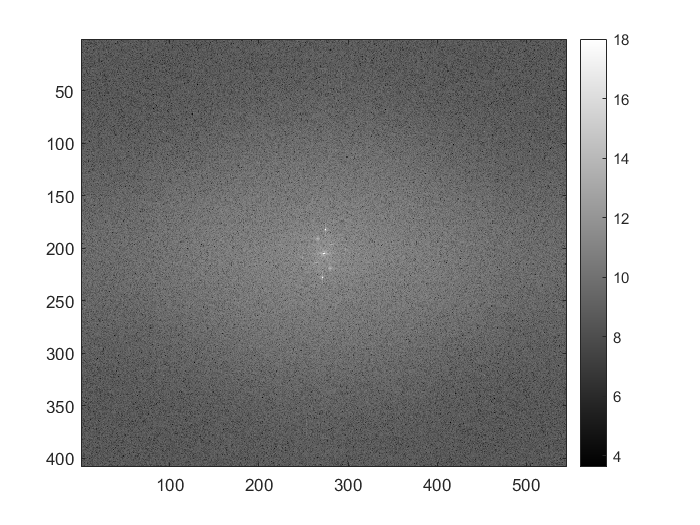

k= [];
m = 1;
for i=1:size(FT,1)
    for j=1:size(FT,2)
        if FT(i,j) > 14
            FT(i,j) = 18;
            k(:,:,m) = [i,j];
            m = m+1;
        end
    end
end
figure;
imagesc(FT)
colorbar()
colormap("gray")

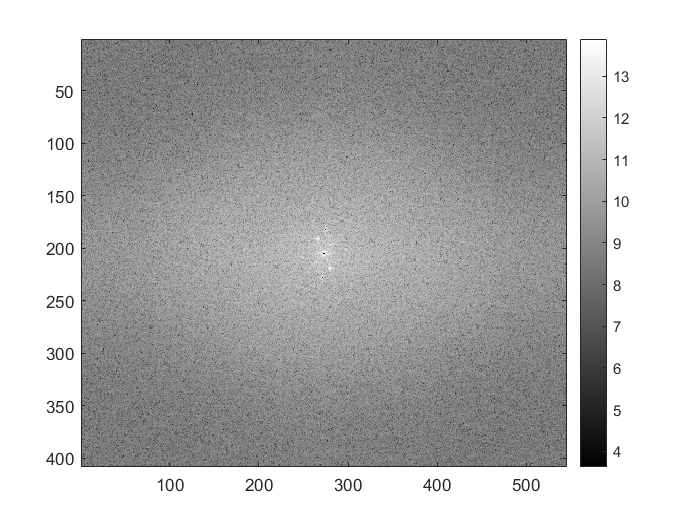

%imSharpen = highpass(FT2,0.5E7,2E7);
% imSharpenView = log(1 + abs(fftshift(imSharpen)));
for i=1:m-1
    FT2(k(1,1,i),k(1,2,i)) = 0;
end
 figure; imagesc(log(abs(FT2)));
 colorbar()
colormap("gray")

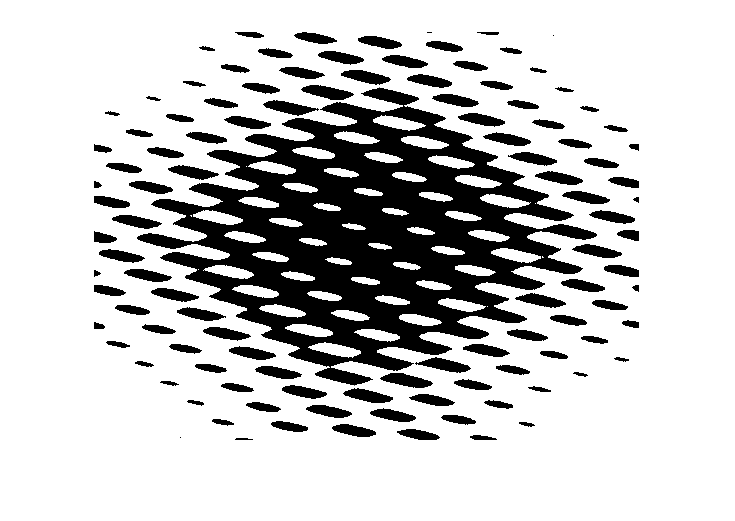

% 
 %g = real(ifft2(ifftshift((FT))));
 g = ifft2(ifftshift(exp(FT) - 1));
 figure; imshow(g);

%[b,a] = butter(3,[0.2 0.6],'stop');
